# 1.4 δ)

## Παράμετροι για την ρύθμιση της βελτιστοποίησης

upper=[1,1,1,1,1,1];
lower=[0,0.05,0.05,0,0,0];
numofvar = 6;

## Ρύθμιση της βελτιστοποίησης

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


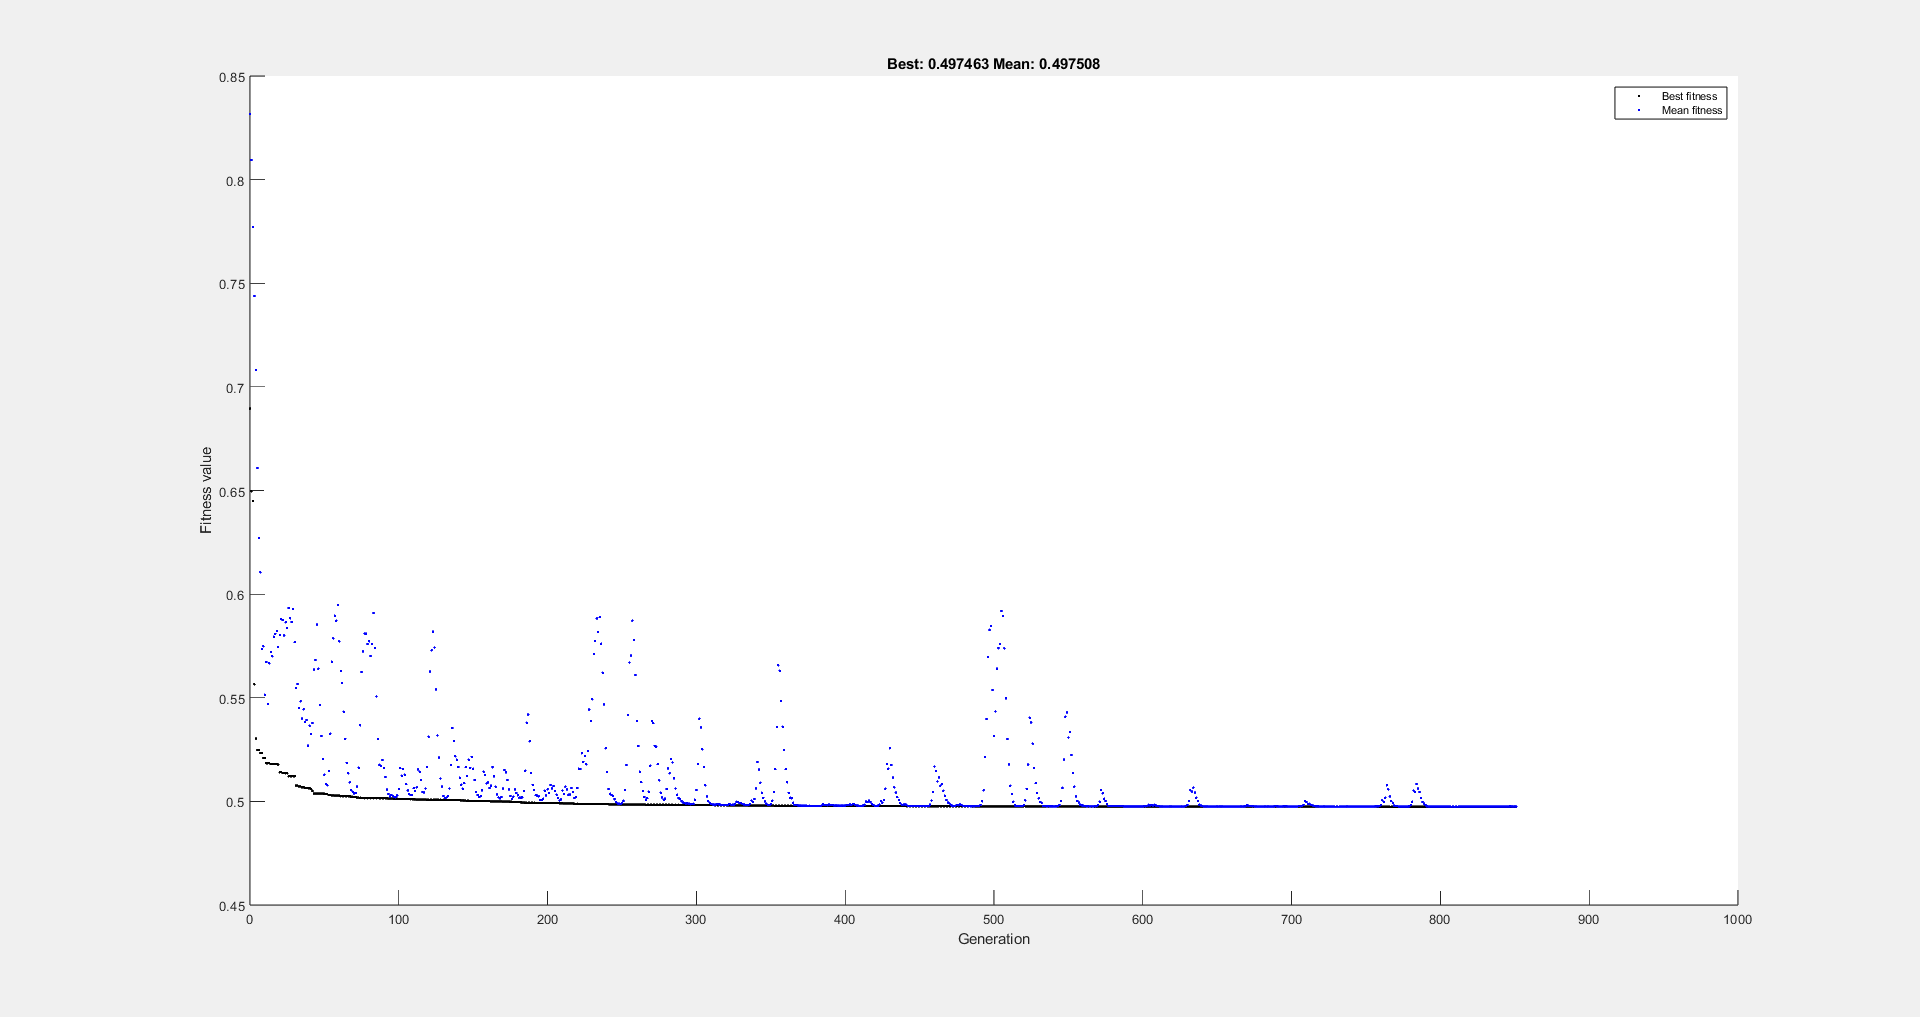

% Set nondefault solver options
options = optimoptions("ga","PopulationSize",200,"MaxGenerations",1000,...
    "MaxStallGenerations",500,"MaxStallTime",200,"PlotFcn","gaplotbestf");

% Solve
[p,minG] = ga(@code14d,numofvar,[],[],[],[],lower,upper,[],...
    [],options);


% Clear variables
clearvars options